k = 10;
seed = 42;
targetColumn = 9; % 9: Heating Load, 10: Cooling Load

data = readtable("../Data/ENB2012_data.xlsx");

Headers = [
    "Relative Compactness"
    "Surface Area"
    "Wall Area"
    "Roof Area"
    "Overall Height"
    "Orientation"
    "Glazing Area"
    "Glazing Area Distribution"
    "Heating Load"
    "Cooling Load"];

data.Properties.VariableNames = Headers;
M = table2array(data);

X = [ones(size(M,1),1), M(:,1:8)];

y = M(:,targetColumn);

ridgeLambda = logspace(-4, 4, 25);
lassoAlpha = logspace(-4, 4, 25);

% Standardize predictors using training-fold statistics only. This keeps the
% scale-dependent regularization strengths comparable without data leakage.
n = size(X, 1);
rng(seed);
fold = zeros(n, 1);
fold(randperm(n)) = mod(0:n-1, k)' + 1;

ridgeRMSE = zeros(numel(ridgeLambda), 1);
lassoRMSE = zeros(numel(lassoAlpha), 1);

for parameterIndex = 1:numel(ridgeLambda)
    foldErrors = zeros(k, 1);

    for foldIndex = 1:k
        validation = fold == foldIndex;
        training = ~validation;

        [Xtraining, Xvalidation] = standardizePredictors(X(training, :), X(validation, :));
        ridgeCoefficients = simple_ridge([ones(sum(training), 1), Xtraining], ...
            y(training), ridgeLambda(parameterIndex));
        predictions = [ones(sum(validation), 1), Xvalidation] * ridgeCoefficients;
        foldErrors(foldIndex) = sqrt(mean((y(validation) - predictions).^2));
    end

    ridgeRMSE(parameterIndex) = mean(foldErrors);
end

for parameterIndex = 1:numel(lassoAlpha)
    foldErrors = zeros(k, 1);

    for foldIndex = 1:k
        validation = fold == foldIndex;
        training = ~validation;

        [Xtraining, Xvalidation] = standardizePredictors(X(training, :), X(validation, :));
        [lassoCoefficients, lassoIntercept] = simple_lasso( ...
            Xtraining, y(training), lassoAlpha(parameterIndex));
        predictions = Xvalidation * lassoCoefficients + lassoIntercept;
        foldErrors(foldIndex) = sqrt(mean((y(validation) - predictions).^2));
    end

    lassoRMSE(parameterIndex) = mean(foldErrors);
end

[bestRidgeRMSE, ridgeIndex] = min(ridgeRMSE);
[bestLassoRMSE, lassoIndex] = min(lassoRMSE);
bestRidgeLambda = ridgeLambda(ridgeIndex);
bestLassoAlpha = lassoAlpha(lassoIndex);

% Refit the selected models on the complete dataset
[Xstandardized, ~, predictorMean, predictorStd] = standardizePredictors(X, X);
ridgeBeta = simple_ridge([ones(n, 1), Xstandardized], y, bestRidgeLambda);
[lassoBeta, lassoIntercept] = simple_lasso(Xstandardized, y, bestLassoAlpha);

fprintf('Ridge: lambda = %.6g, mean CV RMSE = %.6f\n', ...
    bestRidgeLambda, bestRidgeRMSE);

Ridge: lambda = 0.1, mean CV RMSE = 2.949905


fprintf('LASSO: alpha = %.6g, mean CV RMSE = %.6f\n', ...
    bestLassoAlpha, bestLassoRMSE);

LASSO: alpha = 0.464159, mean CV RMSE = 2.949921


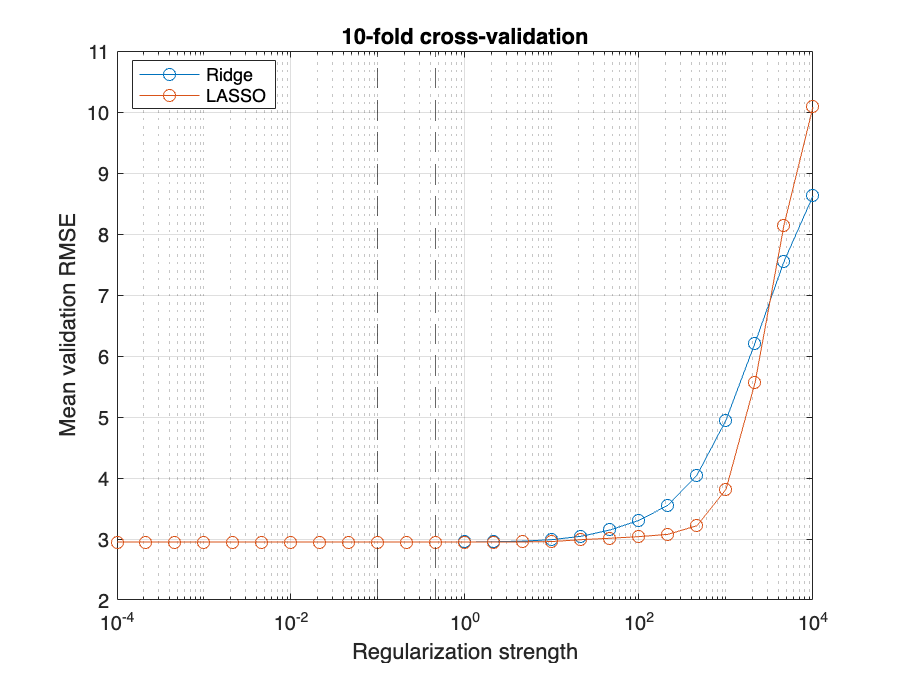


results = struct( ...
    'ridgeLambda', bestRidgeLambda, ...
    'ridgeRMSE', bestRidgeRMSE, ...
    'lassoAlpha', bestLassoAlpha, ...
    'lassoRMSE', bestLassoRMSE, ...
    'predictorMean', predictorMean, ...
    'predictorStd', predictorStd, ...
    'ridgeBeta', ridgeBeta, ...
    'lassoBeta', lassoBeta, ...
    'lassoIntercept', lassoIntercept);

% Plot the cross-validation curves
figure()
semilogx(ridgeLambda, ridgeRMSE, '-o', 'DisplayName', 'Ridge');
hold on;
semilogx(lassoAlpha, lassoRMSE, '-o', 'DisplayName', 'LASSO');
xline(bestRidgeLambda, '--', 'HandleVisibility', 'off');
xline(bestLassoAlpha, '--', 'HandleVisibility', 'off');
grid on;
xlabel('Regularization strength');
ylabel('Mean validation RMSE');
title(sprintf('%d-fold cross-validation', k));
legend('Location', 'best');


function [Xtraining, Xvalidation, predictorMean, predictorStd] = ...
        standardizePredictors(Xtraining, Xvalidation)
    predictorMean = mean(Xtraining, 1);
    predictorStd = std(Xtraining, 0, 1);
    predictorStd(predictorStd == 0) = 1;

    Xtraining = (Xtraining - predictorMean) ./ predictorStd;
    Xvalidation = (Xvalidation - predictorMean) ./ predictorStd;
end